G = zpk(-5,[-1 -2 -3 -4],6);

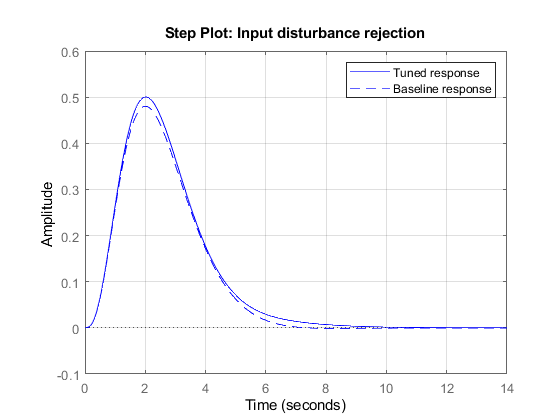

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/2.32056;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.699727;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[Cnew,pidInfo] = pidtune(G,'PIDF',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response_Tuned = getPIDLoopResponse(Cnew,G,'input-disturbance');
Response_Baseline = getPIDLoopResponse(C,G,'input-disturbance');

% Plot the result
stepplot(Response_Tuned,'-', Response_Baseline, '--')
legend('Tuned response', 'Baseline response');
title('Step Plot: Input disturbance rejection')
grid on


% Display system response characteristics
Response = getPIDLoopResponse(Cnew,G,'closed-loop');
disp(stepinfo(Response))

        RiseTime: 1.6542
    SettlingTime: 2.5829
     SettlingMin: 0.9016
     SettlingMax: 1.0052
       Overshoot: 0.5162
      Undershoot: 0
            Peak: 1.0052
        PeakTime: 3.3967




% Clear Temporary Variables
clear Response Response_Tuned Response_Baseline